%% ==== Read CSV ====
data = readtable("Waypoints_with_z4point.csv");

% Convert columns into numeric (รองรับ cellstring / string / numeric)
x = data.x;
y = data.y;
z = data.z;

path_id = convertToNumeric(data.path_id);
type = convertToNumeric(data.type);
cmd = path_id

cmd =     -1
     0
     0
     0
     0
     0
     0
     0
     0
     0


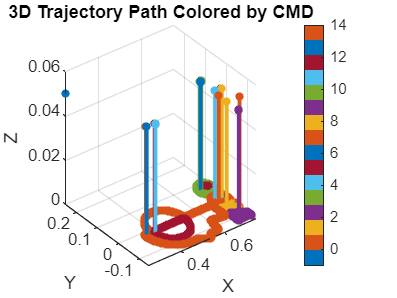

%% ==== Prepare Colors for each cmd ====
cmd_values = unique(cmd);
num_cmd = length(cmd_values);
cmap = lines(num_cmd);

%% ==== 3D Plot ====
figure; hold on; grid on;
xlabel('X'); ylabel('Y'); zlabel('Z');
title('3D Trajectory Path Colored by CMD');
view(3);

%% ==== Plot by Path ID ====
path_ids = unique(path_id);

for i = 1:length(path_ids)
    pid = path_ids(i);

    idx = find(path_id == pid);

    % Plot segments separated by CMD
    for c = 1:num_cmd
        this_cmd = cmd_values(c);
        cidx = idx(cmd(idx) == this_cmd);

        if numel(cidx) > 1
            plot3(x(cidx), y(cidx), z(cidx), ...
                'LineWidth', 2, ...
                'Color', cmap(c, :));
        end
    end
end

scatter3(x, y, z, 20, cmd, 'filled');
colorbar;
colormap(cmap);



%% ==== Helper Function ====
function out = convertToNumeric(col)
    % ถ้าเป็น numeric อยู่แล้ว
    if isnumeric(col)
        out = col;
        return;
    end
    
    % ถ้าเป็น string/cell string
    if iscell(col)
        out = str2double(col);
    elseif isstring(col)
        out = str2double(col);
    else
        error("Unsupported data type");
    end
end
